# GIF PostProcess animation

## Introduction

In these tutorial, you will learn how to post-process the results of your simulations in order to generate **animations** and visualize their evolution. These animations can be particularly useful to understand the behavior of a simulation, compare different configurations, or simply create visual representations of your results.

Although the examples presented in this tutorial use images exported from **ParaView**, the same workflow can be applied to images generated using other software, such as MATLAB, GiD, or any other visualization tool.

The idea is to use MATLAB to process a sequence of images and combine them into a single **GIF**. If you have any questions, feel free to create a new issue in the GitHub repository.

## Image generation and export

Before generating a GIF, we first need to obtain a sequence of images representing the evolution of our simulation.

For this purpose, we can use ParaView to visualize the different time steps of our simulation and export the animation as a sequence of PNG images.

To do so, follow these steps:

- Open your simulation results in ParaView.

- Configure the visualization according to your preferences (representation, color maps, camera position, etc.).

- Navigate through the available time steps to make sure that the simulation is displayed correctly.

- Go to File > Save Animation.

- Select PNG as the output format and configure the desired resolution and frame rate.

- Choose an output folder where all the images will be stored.

Once the export is complete, we should have a sequence of PNG images, with each image representing a different time step of the simulation.

**Note:** It is important to keep the visualization settings consistent throughout the animation. Otherwise, changes in the camera position, color scale, or representation may introduce unwanted variations between frames.

For the purposes of this tutorial, the images are obtained from a 3D Topology Optimization for a cantilever Beam using the Tutorial05_11_TopOpt3DDensityMacroPython. 

## GIF generation using MATLAB

Now that we have our images, we can use MATLAB to combine them into a single animated GIF.

The following script reads all the PNG images from a specified folder, allows us to select a region of interest, resizes the images, and finally generates the GIF.

#### **Inputs**

First, we need to define the input and output filenames, as well as some parameters controlling the animation.

NameFile   = 'TutorialGIF.*.png';      % Filename pattern used to identify the PNG images   
NameOutput = 'GIF_Result.gif';       % Name of the resulting GIF.
output     = fullfile('TutorialGIF_files/',NameOutput);

fps   = 20;         % Desired frame rate of the animation.      
delay = 1/fps;    % Time between consecutive frames.
scale = 0.75;      % Scaling factor used to resize the images.

#### **Reading the images**

Next, we retrieve all the images from the input folder.

files = dir(fullfile('TutorialGIF_files/',NameFile));
files = sort({files.name});  % ensures that they are processed in alphabetical order.

**Note:** Make sure that your images are named consistently so that their alphabetical order matches the chronological order of the simulation. Otherwise, the resulting animation may display the time steps in the wrong sequence.

#### **Selecting the region of interest**

Depending on the software used to generate the images, they may contain additional information that we do not want to include in our animation, such as color bars, legends, axes, or unused margins.

To avoid this, we can interactively select the region of the image that we want to keep.

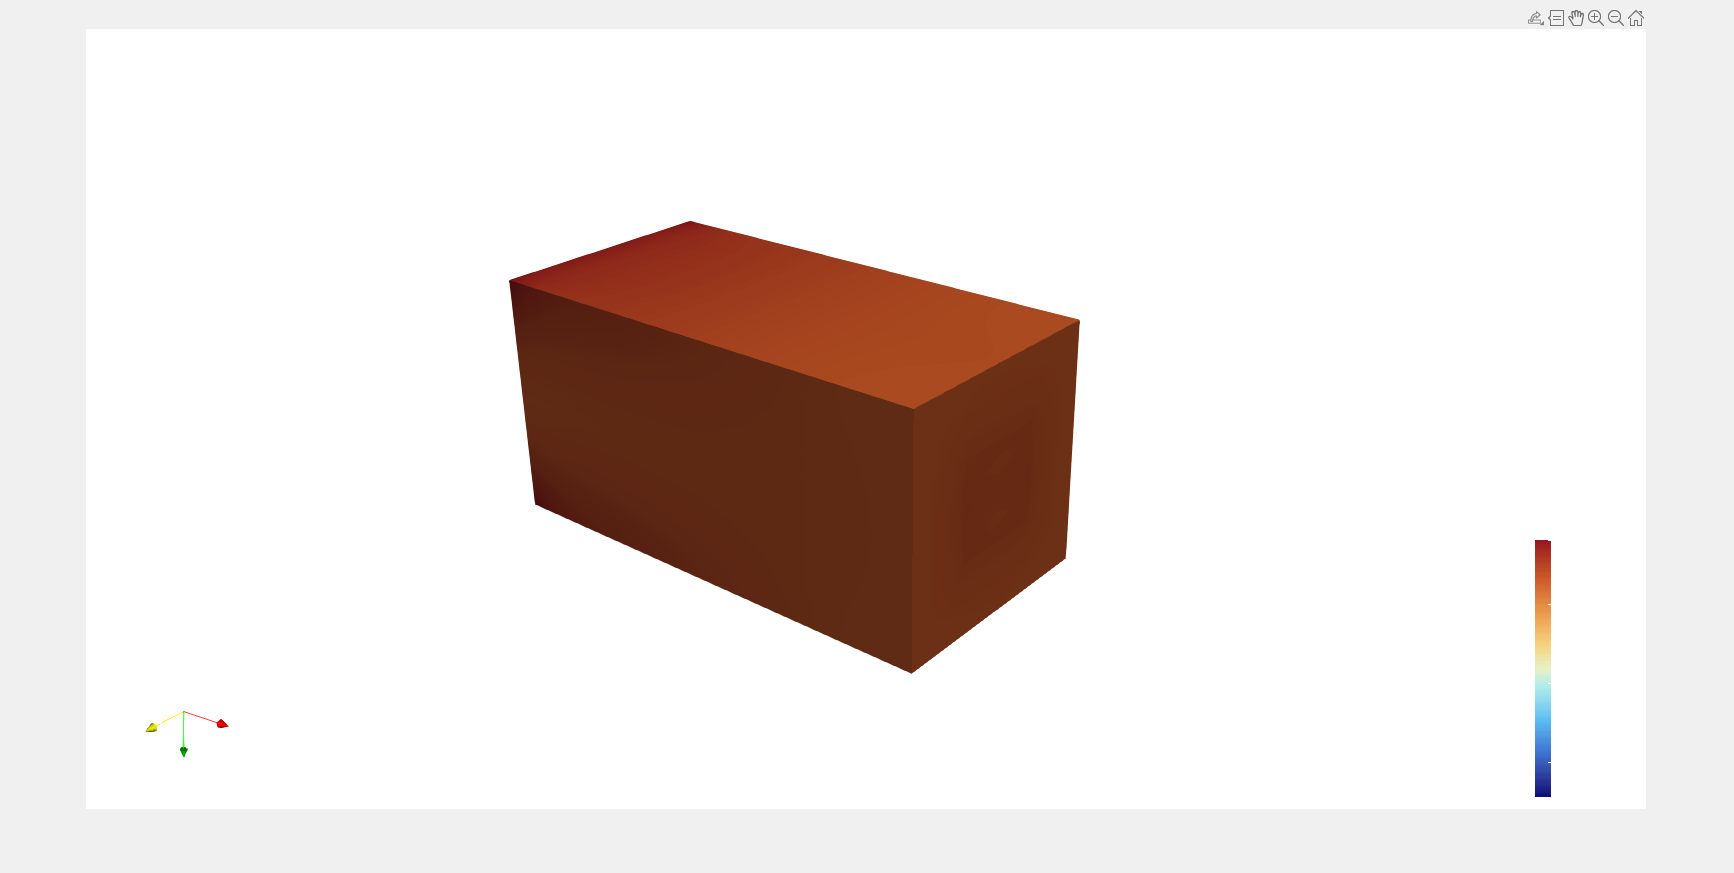

img = imread(files{1});
imshow(img)
rect = getrect;

Once the first image is displayed, `getrect` allows us to draw a rectangle around the desired region. The same rectangular selection will then be applied to every image in the sequence.

#### **Generating the GIF**

Finally, we can process all the images and combine them into an animated GIF.

for k = 1:length(files)
    img = imread(files{k});
    img_crop = imcrop(img, rect);
    img_small = imresize(img_crop, scale);

    [A,map] = rgb2ind(img_small,256);

    if k == 1
        imwrite(A,map,output,'gif', ...
            'LoopCount',inf, ...
            'DelayTime',delay);
    else
        imwrite(A,map,output,'gif', ...
            'WriteMode','append', ...
            'DelayTime',delay);
    end
end

disp('GIF created')

GIF created
